a = imread("cat.jpg");
%a = imread("img2.jpeg");

Procesamiento 

ar = a(:,:,1);
ag = a(:,:,2);
ab = a(:,:,3);

figure(1);subplot(2,2,1); imshow(ag); title("Imagen original");    
ag = double(ag); ag = ag/255; % Normalizado [0-1]
% bg = ag + 100/255;
bg = ag.^0.5;
bg = bg*255;
bg = uint8(bg); 
ag = ag*255; ag = uint8(ag); %Denormalizado

figure(1);subplot(2,2,2); imshow(bg); title("Gamma");

histograma

s = size(a);

s =    480   640     3


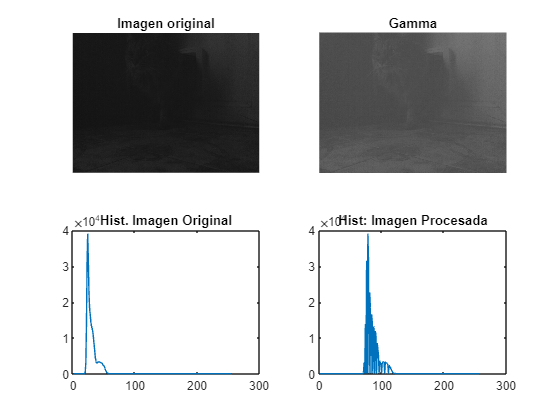

histag = zeros(1,256);
histbg = zeros(1,256);


for f = 1:s(1)
    for c = 1:s(2)
        ng = ag(f,c);
        histag(ng+1) = histag(ng + 1) + 1;
        ng = bg(f,c);
        histbg(ng+1) = histbg(ng + 1) + 1;
    end
end
figure(1);subplot(2,2,3); plot(histag); title("Hist. Imagen Original");
figure(1);subplot(2,2,4); plot(histbg); title("Hist: Imagen Procesada");

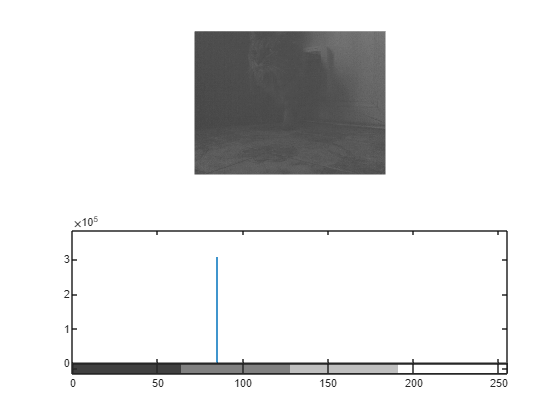




% figure(1);subplot(2,2,3); imhist(a);title("Hist. Imagen Original");
% figure(1);subplot(2,2,4); imhist(bg);title("Hist: Imagen Procesada");
% 
Iimg = bg;
stimg=(Iimg-min(Iimg(:)))/(max(Iimg(:))-min(Iimg(:)))*255;
 

figure(2);subplot(2,1,1);imshow(bg);

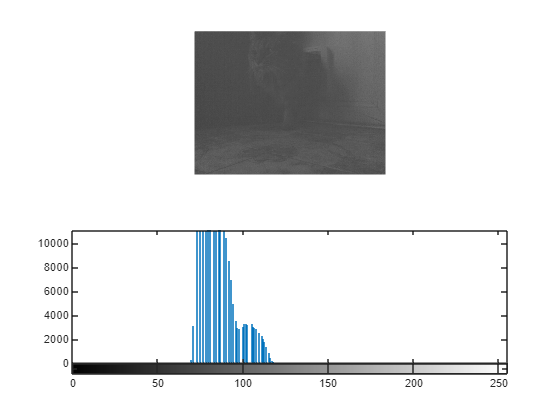

figure(2);subplot(2,1,2);imhist(bg,304);

urls: 

cat: [https://www.kaggle.com/datasets/terrydolan/catmon-cats-dataset](https://www.kaggle.com/datasets/terrydolan/catmon-cats-dataset)

% figure(2);subplot(1,3,1); plot(histag); title("Hist. Imagen Original");
% figure(2);subplot(1,3,2); plot(histbg); title("Hist: gamma 0.5");
% figure(2);subplot(1,3,3); plot(histag); title("Hist. gamma 0.8");

